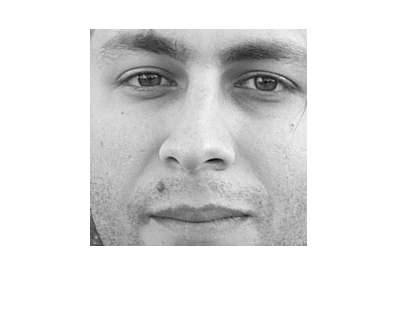

input = imread("db\DB0\db0_2.jpg");
img_gray = rgb2gray(input);
[lenY , lenX] = size(img_gray);

% eye1 = [floor(lenY/2) , 2*floor(lenX/5)];
% eye2 = [floor(lenY/2) , 4*floor(lenX/5)];

eye1 = [floor(lenY/2) , floor(lenX*0.41)];
eye2 = [floor(lenY/2) , floor(lenX*0.56)];

offsetY = floor((eye2(1,2)-eye1(1,2)));
offsetX = floor((eye2(1,2)-eye1(1,2)));

croppedImage = img_gray(eye1(1,1)-offsetY:eye2(1,1)+2*offsetY,eye1(1,2)-offsetX:eye2(1,2)+offsetX);


imshow(croppedImage)

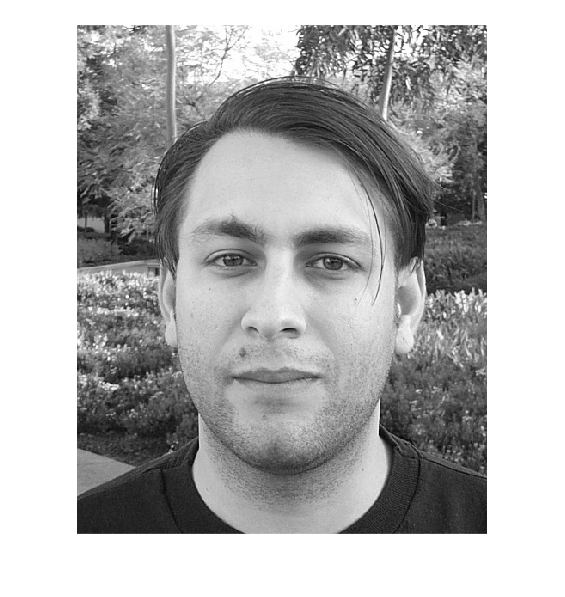

imshow(img_gray)